## Load data

clear;

cupId = 1;

% Load file and cup configurations
[~, cup] = func_loadBasicParams(cupId);

file.path = ['../dataset/20220705_data/', num2str(cupId), 'cup_nail_70dB/'];
file.name = 'F-N3-glass%dcup%d-%d.wav';

% Data cofigurations
config.data.rate = 48000; 

config.data.unit = 40;
config.data.nTrial = 4;

config.data.nData = (ceil(cup.maxAmount / config.data.unit) + 1) * config.data.nTrial; 

% Load data
Amount=[];
cupSpec = 0;

while(cupSpec<=cup.maxAmount)
    for cnt =1:config.data.nTrial
        Amount = vertcat(Amount, cupSpec);
    end
    if(cup.maxAmount - cupSpec == 10) 
        cupSpec = cupSpec + 10;
    else 
        cupSpec = cupSpec + config.data.unit;
    end
end

data = struct();

    for cnt = 1:config.data.nData
        data(cnt).amount = Amount(cnt);
%         data(cnt).amount = floor((cnt - 1) / config.data.nTrial) * config.data.unit;

        [raw, fs] = audioread([file.path, sprintf(file.name, cupId, data(cnt).amount, ...
            rem(cnt - 1, config.data.nTrial) + 1)]);
        
        if fs ~= config.data.rate
            raw = resample(raw, config.data.rate, fs);
        end

        data(cnt).raw = raw;

    end

## Data segmentation

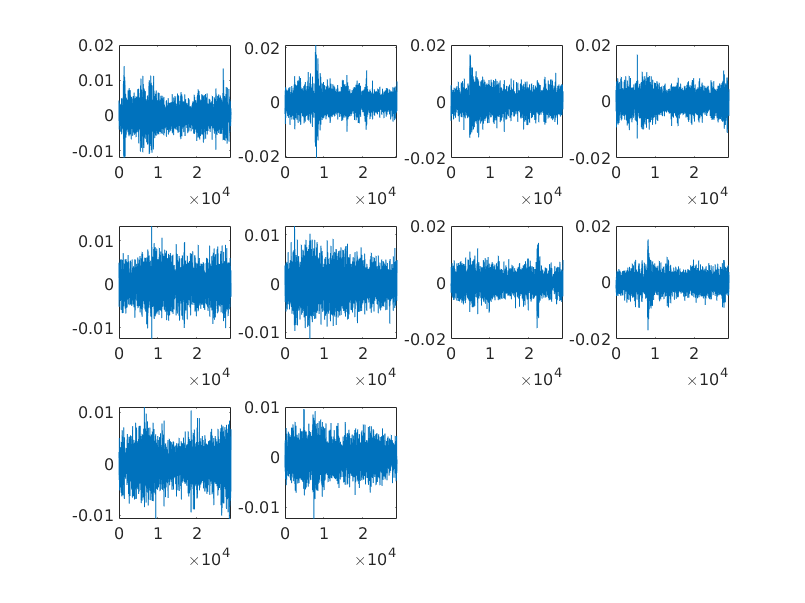

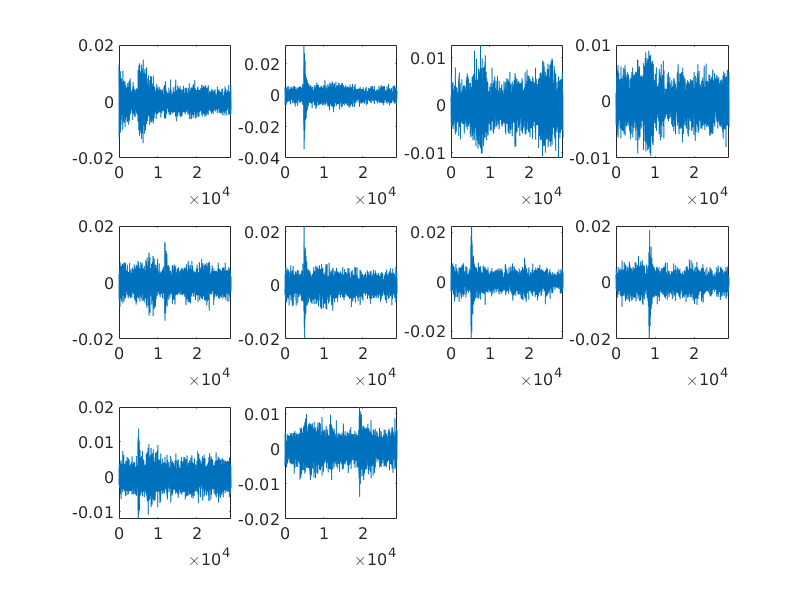

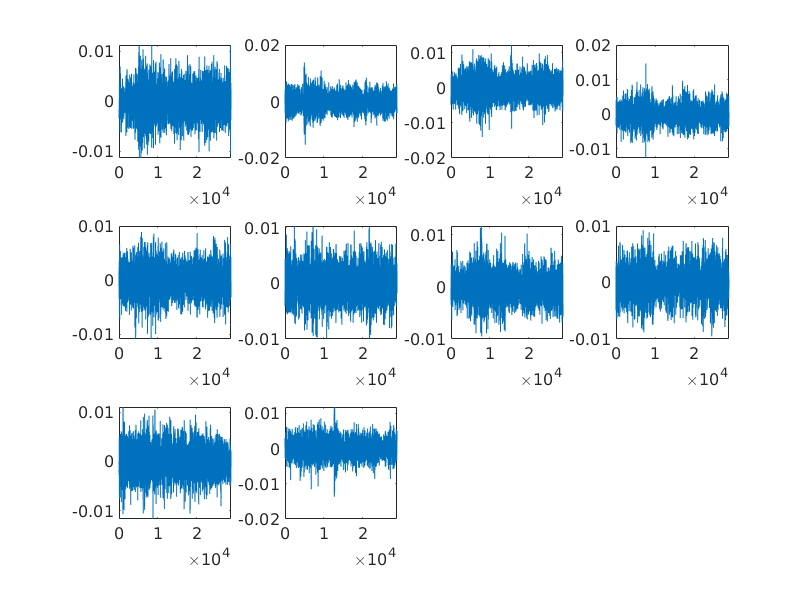

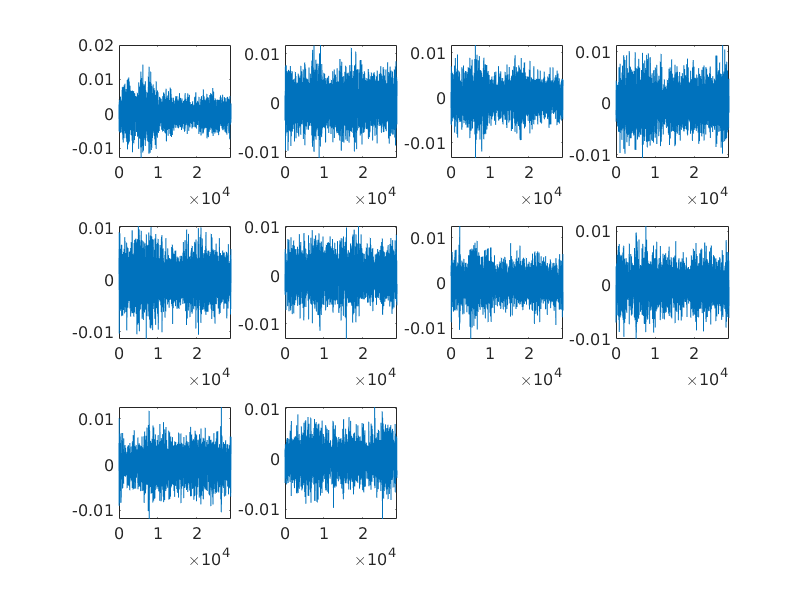

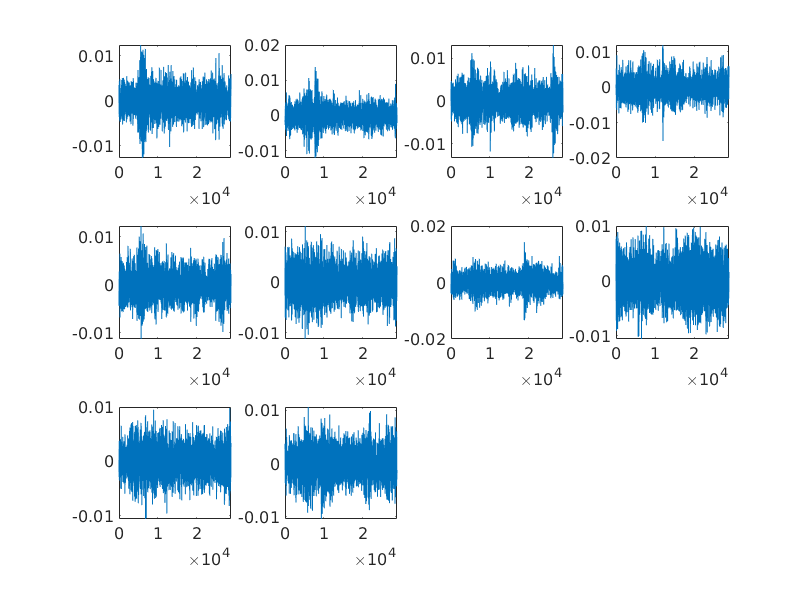

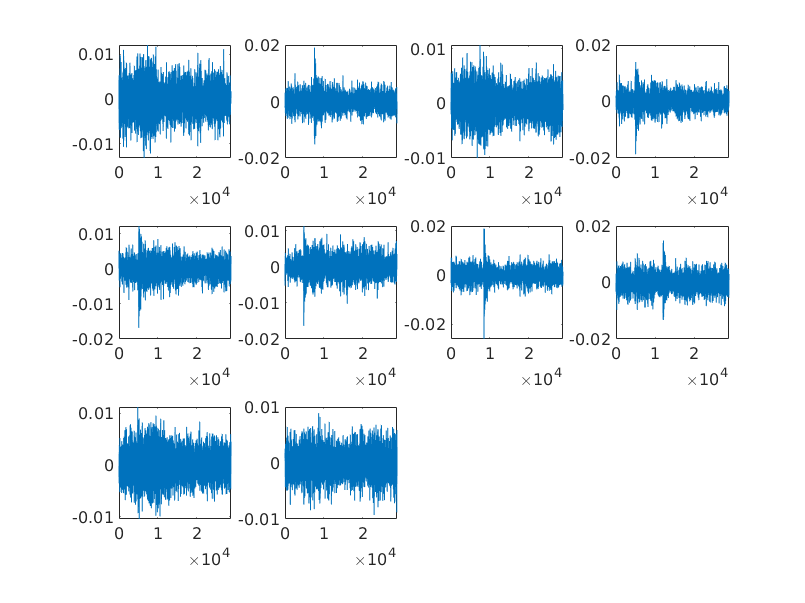

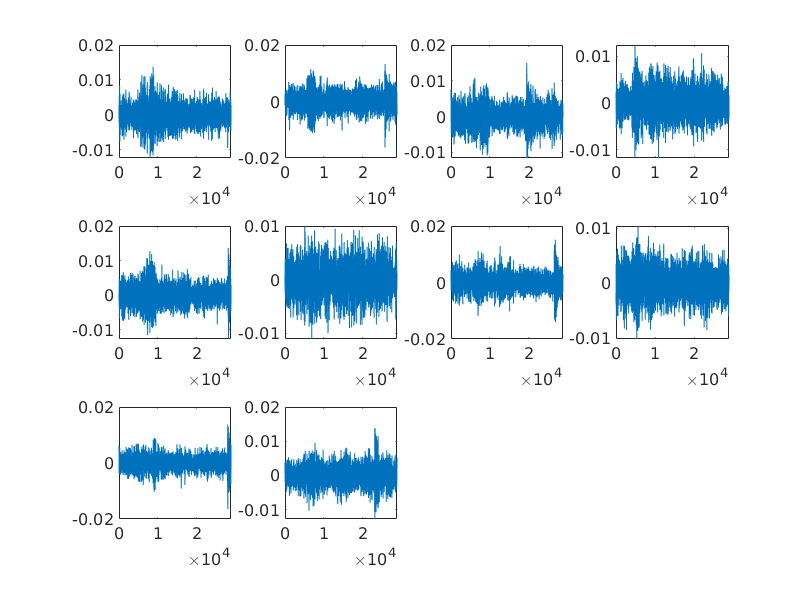

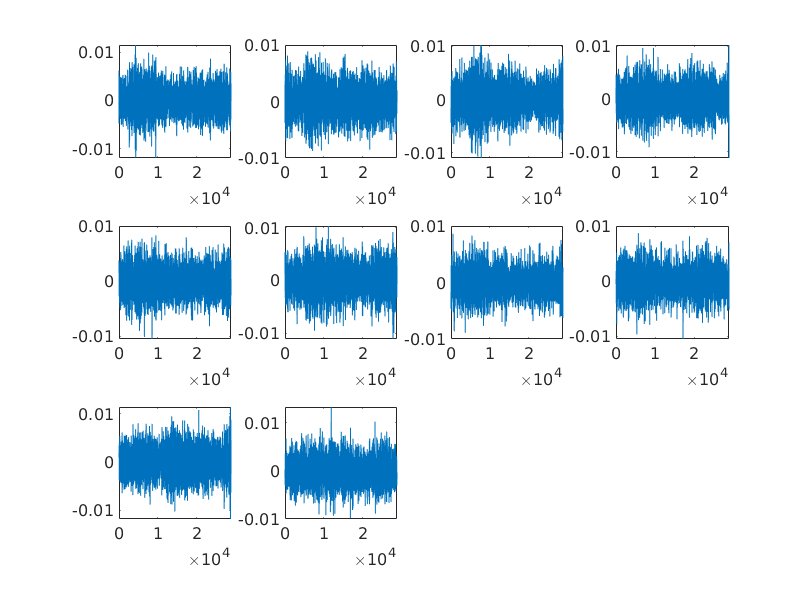

% Detection configurations
config.detect.interval = -ceil(config.data.rate * .1):ceil(config.data.rate * .5 - 1);
config.detect.nTrial = 10;
config.detect.ch = 1;
config.detect.energyWidth = config.data.rate * .1;
config.detect.peakDistance = config.data.rate * .5;

config.detect.startPts = config.data.rate * .5;

tmp = data;
data = struct();

config.debug.nCol = 4;
config.debug.nRow = ceil(config.detect.nTrial / config.debug.nCol);

for cnt = 1:config.data.nData
    cur = tmp(cnt).raw(:, config.detect.ch);
        
    energy = func_calcEnergy(cur, config.detect.energyWidth); % calcEnergy
    energy = energy ./ max(abs(energy)); % normalize

    [pks, locs] = findpeaks(energy, 'MinPeakDistance', config.detect.peakDistance);
    
    [~, idx] = sort(pks, 'descend');
    locs = locs(idx);
    locs(locs < config.detect.startPts) = [];
    locs(locs >= length(tmp(cnt).raw) - config.detect.interval(end)) = [];
    
    for cnt2 = 1:config.detect.nTrial
        data((cnt - 1) * config.detect.nTrial + cnt2).amount = tmp(cnt).amount;
        data((cnt - 1) * config.detect.nTrial + cnt2).location = rem(cnt - 1, 4) + 1;
        data((cnt - 1) * config.detect.nTrial + cnt2).raw = tmp(cnt).raw(locs(cnt2) - ...
            config.detect.energyWidth + config.detect.interval, :);
    end
    
    
    % Just for debugging
    figure
    for cnt2 = 1:config.detect.nTrial
        cur = data((cnt - 1) * config.detect.nTrial + cnt2).raw(:, config.detect.ch);
        
        subplot(config.debug.nRow, config.debug.nCol, cnt2)
        plot(cur)
    end
end

## Store data

matName = [num2str(cupId), 'cup.mat'];
save(matName, 'data')
